# CIE425: Information Theory and Coding

# Course Project: Implementation of H.264 video coding standard

## Mohamed Ali Saleh

## 1. Importing video

% reading the original RGB video.
[vid, frame_rate] = import_vid('xylophone.mpg');

% showing first image of the video.
disp('First frame from the original grey-scaled video');

First frame from the original grey-scaled video


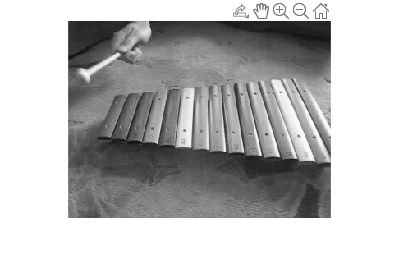

imshow(uint8(vid(:,:,1)));


% saving original file again in greyscale.
write_vid(vid, 'E:\ZC\year4_2022_2023\FALL22\CIE425\project\vid_original', frame_rate);

## 2. Using huffman coding

### 2.1. Low quantization.

% Data
quant_table = get_low_quant_table();
frame_size = size(vid(:,:,1));

% Encoding
[encoded_vid, compression_ratio_huffman_low, huffman_tree] = encode_vid(vid, quant_table, 'h');

% decoding
decoded_vid = decode_vid(encoded_vid, huffman_tree, quant_table, frame_size, 'h');

% displaying first frame of the decoded vidء
disp('First frame from the decoded grey-scaled video using huffman encoding and low quantization');

First frame from the decoded grey-scaled video using huffman encoding and low quantization


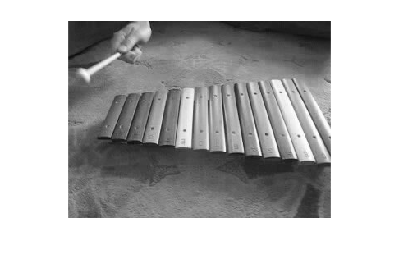

imshow(uint8(decoded_vid(:,:,1)));


% saving decoded video
write_vid(decoded_vid, 'E:\ZC\year4_2022_2023\FALL22\CIE425\project\vid_huffman_low', frame_rate);

### 2.2. High quantization.

% Data
quant_table = get_high_quant_table();
frame_size = size(vid(:,:,1));

% Encoding
[encoded_vid, compression_ratio_huffman_high, huffman_tree] = encode_vid(vid, quant_table, 'h');

% decoding
decoded_vid = decode_vid(encoded_vid, huffman_tree, quant_table, frame_size, 'h');

% displaying first frame of the decoded vid
disp('First frame from the decoded grey-scaled video using huffman encoding and high quantization');

First frame from the decoded grey-scaled video using huffman encoding and high quantization


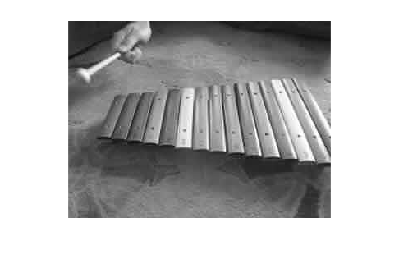

imshow(uint8(decoded_vid(:,:,1)));


% saving decoded video
write_vid(decoded_vid, 'E:\ZC\year4_2022_2023\FALL22\CIE425\project\vid_huffman_high', frame_rate);

### 2.3. Comparison between high and low quantizations using huffman encoding.

disp('Low quantization using huffman')

Low quantization using huffman


disp(compression_ratio_huffman_low)

          4.38134863994726



disp('High quantization using huffman')

High quantization using huffman


disp(compression_ratio_huffman_high)

          17.3589578661986



## 3. Using Arithmetic coding

### 2.1. Low quantization

% Data
quant_table = ones(8);
frame_size = size(vid(:,:,1));

% Encoding
[encoded_vid, compression_ratio_airthmetic_low, huffman_dict] = encode_vid(vid(:,:,1), quant_table, 'a');

% decoding
decoded_vid = decode_vid(encoded_vid, huffman_dict, quant_table, frame_size, 'a');

% saving decoded video
write_vid(vid, 'E:\ZC\year4_2022_2023\FALL22\CIE425\project\vid_huffman_low', frame_rate);

% compression ratio
disp('Compression ratio for low quantization using arithmetic coding = ' + str(compression_ratio_airthmetic_low))

### 2.2. High quantization

% Data
quant_table = ones(8);
frame_size = size(vid(:,:,1));

% Encoding
[encoded_vid, compression_ratio_airthmetic_high, huffman_dict] = encode_vid(vid(:,:,1), quant_table, 'a');

% decoding
decoded_vid = decode_vid(encoded_vid, huffman_dict, quant_table, frame_size, 'a');

% saving decoded video
write_vid(vid, 'E:\ZC\year4_2022_2023\FALL22\CIE425\project\vid_huffman_low', frame_rate);

% compression ratio
disp('Compression ratio for high quantization using arithmetic coding = ' + str(compression_ratio_airthmetic_high))

## 5. User-defined functions

### 5.0. Video

#### 5.0.1 video importing

function [grey_frames, frame_rate] = import_vid(vid_path)
    
    %initialize output.
    grey_frames = []; % This will make the greyscale image in double, which is necessary for computations, but you must transfer it to uint8 if you intend to use imshow()

    % reading video from path into video object.
    vid_obj = VideoReader(vid_path);

    % extracting frames from video object.
    vid_frames = read(vid_obj);

    % extracting frame rate.
    frame_rate = vid_obj.FrameRate;

    % looping over frames.
    for ind = 1:size(vid_frames, 4)

        % transform each frame into greyscale
        grey_frames(:,:,ind) = rgb2gray(vid_frames(:,:,:,ind));

    end
end

#### 5.0.2 Video saving

function write_vid(vid, vid_path, frame_rate)
    
    % create a VideoWriter object
    writerObj = VideoWriter(vid_path);

    % set the frame rate
    writerObj.FrameRate = frame_rate;

    %open stream to the VideoWriter
    open(writerObj);

    % play the video
    nframes = size(vid, 3);
    for i = 1:nframes
        writeVideo(writerObj,uint8(vid(:,:,i)));
    end

end

### 5.1. Video encoding

function [encoded_vid, compression_ratio, huffman_tree] = encode_vid(vid, quant_table, coding)

    % initialize output
    encoded_vid = [];

    % original sizes of a single frame.
    x_original = size(vid, 1);
    y_original = size(vid, 2);

    % rounding up frame size to multiples of 16.
    x = ceil(x_original/16)*16;
    y = ceil(y_original/16)*16;
    
    % for every frame in vid.
    nframes = size(vid,3);
    for i = 1:nframes % index of the current frame.
        
        %  get current frame
        frame = vid(:,:,i);

        % resize the frame if it cannot be divided into 16×16 blocks.
        if x ~= size(frame, 1)
            frame = [frame;zeros(x - x_original, y_original)];
        end
        if y ~= size(frame, 2)
            frame = [frame zeros(x_original, y - y_original)];
        end

        % temporal model.
        if i~=1
            [temporal_encoded, motion_vectors] = temporal_encoder(frame, reference_frame);
        else
            temporal_encoded = frame;
            reference_frame = frame;
            motion_vectors = zeros(1,2*x*y/(16*16));
        end

        % spatial model.
        spatial_encoded = spatial_encoder(temporal_encoded, quant_table);

        % Add the frame to output sequence.
        encoded_vid = [encoded_vid spatial_encoded motion_vectors];

    end

    % entropy encoder.
    [encoded_vid, huffman_tree] = entropy_encoder(encoded_vid, coding);


    % compression ratio
    compression_ratio = x_original * y_original * nframes * 8 / length(encoded_vid);
end

### 5.2. Video decoding

function decoded_vid = decode_vid(encoded_vid, huffman_tree, quant_table, frame_size, coding)

    % initialize output.
    decoded_vid = [];

    % entropy encoding.
    entropy_decoded = entropy_decoder(encoded_vid, huffman_tree, coding);

    % number of elements per a frame.
    scaled_frame_size = [ceil(frame_size(1)/16) ceil(frame_size(2)/16)].*16;
    frame_elements = scaled_frame_size(1)*scaled_frame_size(2);
    vectors_elements = 2*frame_elements/(16*16);

    % current frame index.
    frame_ind = 1;

    % for every encoded frame.
    for i = 1:frame_elements+vectors_elements:length(entropy_decoded)

        % spatial decoding.
        spatial_decoded = spatial_decoder(entropy_decoded(i:i+frame_elements-1), quant_table, scaled_frame_size);

        % temporal decoding
        if i ~= 1
            temporal_decoded = temporal_decoder(spatial_decoded, decoded_vid(:,:,1), entropy_decoded(i+frame_elements:i+frame_elements+vectors_elements-1));
        else
            temporal_decoded = spatial_decoded;
        end

        % Adding frame to output sequence.
        decoded_vid(:,:,frame_ind) = temporal_decoded;
        frame_ind = frame_ind + 1;
        
    end
end

### 5.3. Temporal model

#### 5.3.1. Temporal encoder

function [temporal_encoded, motion_vectors] = temporal_encoder(cur_frame, ref_frame)

    % Sizes of current and reference frame must be equal.
    assert(all(all(size(cur_frame) == size(ref_frame))), 'Temporal encoder: cur_frame and ref_frame must have same size');

    % both dimensions must be divisible by 16.
    assert(mod(size(cur_frame, 1), 16) == 0, 'Temporal encoder: dimesions must be multiples of 16');
    assert(mod(size(cur_frame, 2), 16) == 0, 'Temporal encoder: dimesions must be multiples of 16');

    % initialize output.
    temporal_encoded = zeros(size(cur_frame));
    motion_vectors = [];

    % Looping over every 16×16 block.
    for ic = 1:16:size(cur_frame, 1)
        for jc = 1:16:size(cur_frame, 2)

            % find most similar block.
            [ir, jr] = estimate_block(ic, jc);

            % fill in the residual of this block in the output.
            compensate_block(ic, jc, ir, jr);

        end
    end

    % Auxiliary functions.
    function [ir, jr] = estimate_block(ic, jc)

        % current block.
        cur_block = cur_frame(ic:ic+15, jc:jc+15);

        % search area indices.
        i_start = max(ic-32, 1);
        j_start = max(jc-32, 1);
        i_end = min(ic+16, size(cur_frame, 1) - 16 + 1);
        j_end = min(jc+16, size(cur_frame, 2) - 16 + 1);

        % initialize output.
        ir = ic;
        jr = jc;
        mse = mean_square_error(cur_block, ref_frame(ic:ic+15, jc:jc+15)); % mean square error.

        % find start indices of the most similar block.
        for i = i_start:i_end
            for j = j_start:j_end
                new_mse = mean_square_error(cur_block, ref_frame(i:i+15, j:j+15));
                if new_mse < mse
                    jr = j;
                    ir = i;
                    mse = new_mse;
                end
            end
        end
        
    end

    function compensate_block(ic, jc, ir, jr)
        
        % appending the residual.
        temporal_encoded(ic:ic+15, jc:jc+15) = cur_frame(ic:ic+15, jc:jc+15) - ref_frame(ir:ir+15, jr:jr+15);

        % appending the motion vector.
        motion_vectors = [motion_vectors ir-ic jr-jc];
    end

    function MSE = mean_square_error(X, Y)
        E = abs(Y-X).^2;
        MSE = sum(E(:))/numel(E);
    end
end

#### 5.3.2. Temporal decoder

function temporal_decoded = temporal_decoder(cur_frame, ref_frame, motion_vectors)

    % Sizes of spatial_decoded and temporal_decoded frames must be equal.
    assert(all(all(size(cur_frame) == size(ref_frame))), 'Temporal decoder: spatial_decoded and temporal_decoded must have same size');

    % both dimensions must be divisible by 16.
    assert(mod(size(cur_frame, 1), 16) == 0, 'Temporal decoder: dimesions must be multiples of 16');
    assert(mod(size(cur_frame, 2), 16) == 0, 'Temporal decoder: dimesions must be multiples of 16');
    
    % initialize output.
    temporal_decoded = zeros(size(cur_frame));

    % motion vector index.
    ind = 1;

    % Looping over every 16×16 block.
    for ic = 1:16:size(cur_frame, 1)
        for jc = 1:16:size(cur_frame, 2)

            % compensate and sum.
            im = ic + motion_vectors(ind);
            jm = jc + motion_vectors(ind+1);
            temporal_decoded(ic:ic+15, jc:jc+15) = cur_frame(ic:ic+15, jc:jc+15) + ref_frame(im:im+15, jm:jm+15);

            % next motion vector
            ind = ind + 2;
        end
    end
end

### 5.4. Spatial model (JPEG without entropy encoding)

#### 5.4.1. spatial encoder

function spatial_encoded = spatial_encoder(img, quant_table)

    % divide the image into 8×8 blocks.
    blocks_img = divide_block(img);
    
    % Final encoded signal.
    spatial_encoded = [];
    
    % For every 8×8 block in the image.
    for i = 1:length(blocks_img)
        
        % taking the dct of the block.
        dct_spectrum = take_dct(blocks_img{i});
        
        % dividing by entries in the quantization table.
        quantized_dct = divide_quant(dct_spectrum, quant_table);
        
        % convert 2D to 1D using serpentine pattern.
        linear_seq = serpentine_pattern(quantized_dct);
        
        % collecting all divided 1D blocks into one linear sequence.
        spatial_encoded = [spatial_encoded linear_seq];

    end
end

**Function to divide frame into 8×8 blocks**

function blocks_img = divide_block(img)
    
    %blocks is a cell array.
    blocks_img = {};

    % x dimension of the image.
    imx = size(img, 1);
    
    % y dimenstion of the image.
    imy = size(img, 2);
    
    % looping throgh blocks
    for sx = 1:8:imx
        for sy = 1:8:imy
            % looping in the block
            tmp = [];
            for i = sx:sx+7
                tmp0 = [];
                for j = sy:sy+7
                    if i > imx || j > imy
                        tmp0 = [tmp0 0];
                    else
                        tmp0 = [tmp0 img(i, j)];
                    end    
                end
                tmp = [tmp; tmp0];
            end
            blocks_img = [blocks_img tmp];
        end
    end
end

**Funcion to take dct**

function dct_result= take_dct(block_8)
    [R,C]=size(block_8);
    %intialize the basis block
    basis=zeros(R,C);
    if R~=8 || C~=8
        disp('Error in block size');
    end
    %looping over the size of the basis and size of the input
    dct_result=zeros(8,8);
    for u=0:7
        for v=0:7
            for x=0:7
                for y=0:7
                    % constructing the basis function
                    basis(x+1,y+1)=(cos((1/16)*(2*x+1)*u*pi))*(cos((1/16)*(2*y+1)*v*pi));
                end
            end
            % multiplying each pixel to the corresponding basis block and averaging them then storing in dct_result
            dct_result(u+1,v+1)=sum(sum(block_8.*basis));
        end
    end
    % Now Scaling
    dct_result(1,1)=(1/64)*dct_result(1,1);             %The first value in the block /64
    dct_result(1,2:8)=(1/32)*dct_result(1,2:8);         %The first row /32
    dct_result(2:8,1)=(1/32)*dct_result(2:8,1);         %The first column /32
    dct_result(2:8,2:8)=(1/16)*dct_result(2:8,2:8);     % the rest of the block/16
end

**Function to quantize block.**

function quantized_dct = divide_quant(dct_spectrum, quant_table)
    quantized_dct = round(dct_spectrum ./ quant_table);
end

**Function to transform block from 2D to 1D using serpentine pattern.**

function linear_seq = serpentine_pattern(quantized_dct)
    % quantized_dct must be 8×8.
    assert(size(quantized_dct, 1)<=8 && size(quantized_dct, 2)<=8, "input must be an 8×8 block");
    
    % final output sequence.
    linear_seq = [];
    
    % following the serpentine pattern, divided into several iterations.
    s = [1,1]; % start of the iteration
    while true
        
        % The end of this iteration.
        e = flip(s);
        
        
        % iterate to append cells in the diagonal from start(s) to end(e).
        cells = [s(1):(-1)^(s(1)>e(1)):e(1); s(2):(-1)^(s(2)>e(2)):e(2)];
        for i = 1:size(cells, 2)
            linear_seq = [linear_seq quantized_dct(cells(1, i), cells(2, i))];
        end
        
        if all(s == [8,8])
            break;
        end
        
        % next start sould be the end but shifted with one cell either to
        % the right or to down depending on the iteration. The method I
        % will follow here is to increment the maximum dimension (either x
        % or y) by 1 till it reaches 8 (maximum value it can take) and then
        % keep incrementing the other till both reach [8,8].
        s = e;
        
        if s(1) > s(2)
            i = 1;
        else
            i = 2;
        end
        
        m = s(i);

        if m ~= 8
            s(i) = s(i) + 1;
        else
            s(mod(i,2)+1) = s(mod(i,2)+1) + 1;
        end 
    end
end

#### 5.4.2. spatial decoder

function spatial_decoded = spatial_decoder(entropy_decoded, quant_table, img_size)
    
    % construct 8*8 blocks from the linear sequence.
    lin_blocks = lin2blocks(entropy_decoded);
    
    % initializations
    spatial_decoded = [];
    decoded_row = [];
        
    % for every 8*8 block
    for i = 1:length(lin_blocks)
        
        % transform the block into 8*8 block by reverse serpentine pattern.
        block_img = anti_serpentine(lin_blocks{i});
        
        % multiply by the quantization table
        anti_quantized = anti_quantize(block_img, quant_table);
        
        % take the IDCT.
        idct_signal = take_idct(anti_quantized);
        
        % append block to the image.
        decoded_row = [decoded_row idct_signal];
        if size(decoded_row, 2) >= img_size(2)
            spatial_decoded = [spatial_decoded; decoded_row];
            decoded_row = [];
        end     
    end
end

**Function to separate blocks from 1D sequence.**

function blocks = lin2blocks(lin)
    blocks = {};
    block = [];
    for i = 1:length(lin)
        block = [block lin(i)];
        if mod(i,8*8) == 0
            blocks = [blocks block];
            block = [];
        end
    end
end

**Function to reverse the serpentine pattern.**

function block_img = anti_serpentine(linear_seq)
    
    %initializing the block sequence.
    block_img = zeros(8);

    % following the serpentine pattern, divided into several iterations.
    ind = 1; %index of the next element in the linear sequence.
    s = [1,1]; % start of the iteration
    while true
        
        % The end of this iteration.
        e = flip(s);
        
        % iterate to append cells in the diagonal from start(s) to end(e).
        cells = [s(1):(-1)^(s(1)>e(1)):e(1); s(2):(-1)^(s(2)>e(2)):e(2)];
        for i = 1:size(cells, 2)
            block_img(cells(1, i), cells(2, i)) = linear_seq(ind);
            ind = ind + 1;
        end
        
        if all(s == [8,8])
            break;
        end
        
        % next start sould be the end but shifted with one cell either to
        % the right or to down depending on the iteration. The method I
        % will follow here is to increment the maximum dimension (either x
        % or y) by 1 till it reaches 8 (maximum value it can take) and then
        % keep incrementing the other till both reach [8,8].
        s = e;
        
        if s(1) > s(2)
            i = 1;
        else
            i = 2;
        end
        
        m = s(i);

        if m ~= 8
            s(i) = s(i) + 1;
        else
            s(mod(i,2)+1) = s(mod(i,2)+1) + 1;
        end 
    end
end

**Function to multiply a given 8×8 block by a given quantization table.**

function anti_quantized = anti_quantize(block_img, qtable)
    anti_quantized = block_img .* qtable;
end

**Function to take the IDCT of a given 8×8 block.**

function idct_result = take_idct(block_8)
    [R,C]=size(block_8);
    %Intializations
    basis=zeros(R,C);
    if R~=8 || C~=8
        disp('Error in block size');
    end
    %looping over the size of the basis and size of the input
    idct_result=zeros(8,8);
    for u=0:7
        for v=0:7
            for x=0:7
                for y=0:7
                    %constructing the basis block
                    basis(x+1,y+1)=(cos((1/16)*(2*x+1)*u*pi))*(cos((1/16)*(2*y+1)*v*pi));
                end
            end
            % multiplying each value of encoded_block to the corresponding
            % basis block and summing the result and storing it in the result_Idct block
            idct_result=idct_result+block_8(u+1,v+1)*basis;
        end
    end
end

### 5.5. Entropy coding

#### 5.5.1. Entropy encoder

function [huffman_encoded, huffman_tree] = entropy_encoder(linear_seq, coding)

    % perform run-length encoding.
    run_length_encoded = run_length_encode(linear_seq);
    
    if coding == 'h'

        % huffman encoding
        [huffman_encoded, huffman_tree] = huffman_encode(run_length_encoded);

    else
        % arithmetic encoding
        [huffman_encoded, huffman_tree] = arithmetic_encode(run_length_encoded);

    end

end

**Function to perform run-length encoding**

function run_length_encoded = run_length_encode(linear_seq)

    % initializations.
    run_length_encoded = []; %output sequence.
    running_0s = 0; % variable to count the number of consecutive zeros.
    
    % looping on every element in the input seq.
    for i = 1:length(linear_seq)
        
        % we meet a zero.
        if(linear_seq(i) == 0)
            running_0s = running_0s + 1; %increment running zeros.
        else % a non-zero element.
            
            if running_0s ~= 0 % we meet an elemnt with running zeros before it.
                run_length_encoded = [run_length_encoded 0 running_0s];
                running_0s = 0;
            end
            run_length_encoded = [run_length_encoded linear_seq(i)];
        end
    end
    
    % in case of trailing zeros.
    if running_0s ~= 0
        run_length_encoded = [run_length_encoded 0 running_0s];
    end
end

**Function to perform huffman encoding**

function [encoded_seq, huffman_tree] = huffman_encode(linear_seq)

    % get list of all unique symbols.
    symbols = num2cell(unique(linear_seq));

    % probabilities of symbols.
    probs = zeros(1,length(symbols));
    for j = 1:length(symbols)
        probs(j) = sum(linear_seq==symbols{j})/length(linear_seq);
    end

    % building huffman tree for encoding and decoding.
    huffman_tree = build_huffman_tree(probs, symbols);

    % generating huffman codes from huffman tree.
    codes = huffman_encoder(huffman_tree, symbols, probs);

    % generating the encoded sequence from codes
    encoded_seq = huffman_sequence_encoder(codes, linear_seq);

    %huffman_dict = huffmandict(symbols, probs);
    %encoded_seq = huffmanenco(linear_seq, huffman_dict);

    function tree = build_huffman_tree(probs, symbols)
        % Builds a tree with an implementation based on the 'cell array'.
        % This tree is used later for both operations encoding and decoding.
        assert(length(probs) == length(symbols), 'Number of probabilities and symbols must match!');
        assert(length(probs) >= 1, 'No elements provided!');
        
        if length(probs) == 1
            tree = symbols;
        else
            [probs, Is] = sort(probs);
            probs = [probs(1)+probs(2) probs(3:length(probs))];
            symbols = symbols(Is);
            symbols = {{symbols{1}, symbols{2}}, symbols{3:length(symbols)}};
            tree = build_huffman_tree(probs, symbols);
        end
    end

    function codes = huffman_encoder(tree, symbols, probs)
        % Generates a cell array of 3 columns, representing the symbol, code,
        % and probability for each entry, respectively.

        % cell array of codes.
        codes = {};
        sub_huffman_encoder(tree{1}, []);

        % auxiliary sub function for recursive implementation.
        function sub_huffman_encoder(subtree, code)

            % reached a symbol.
            if ~isequal(class(subtree), 'cell')

                % get probability of the current symbol.
                prob = probs([symbols{:}] == subtree);

                % append the symbol, its code, and its probability.
                codes = [codes;{subtree, code, prob}];
            
            % didn't reach a symbol yet. Continue recurcsion.
            else
                sub_huffman_encoder(subtree{1}, [code 0]);
                sub_huffman_encoder(subtree{2}, [code 1]);
            end
        end

        if length(codes) == 0
            codes = [codes;{tree{1}, 0}];
        end
    end

    function codes_sequence = huffman_sequence_encoder(codes, sequence)
        % Takes as input the mapper from symbols to corresponding codes, and
        % the sequence of symbols intended to be coded. Returns a sequence of
        % 0s and 1s (coded symbols).
        codes_sequence = [];
        for i = 1:length(sequence)
            codes_sequence = [codes_sequence codes{[codes{:,1}] == sequence(i), 2}];
        end
    end
end

**Function to perform arithmetic encoding**

function [code_sequence, symbols_probs] = arithmetic_encode(sequence)

    % adding trailing zeros to sequence in case it is length it is not
    % divisible by 10.
    sequence = [sequence zeros(1, mod(5-mod(length(sequence), 5), 5))];
    assert(mod(length(sequence), 5) == 0, 'length of sequence is not divisible by 10');

    % get list of all unique symbols.
    symbols = unique(sequence);

    % probabilities of symbols.
    probs = zeros(1,length(symbols));
    for j = 1:length(symbols)
        probs(j) = sum(sequence==symbols(j))/length(sequence);
    end
    
    % Prepare a prefix sum array of the probabilities.
    accum_probs = zeros([1 length(probs)+1]);
    for i=1:length(probs)
        accum_probs(i+1) = accum_probs(i)+probs(i);
    end

    % initialize output
    code_sequence = {};

    % partitioning sequences.
    for i = 1:5:length(sequence)
        code_sequence = [code_sequence sub_huffman_encode(i, i+4)];
    end

    %zipping symbols and probs together
    symbols_probs = [symbols;probs];

    % auxiliary functions.
    % function to find the code of a given partition from the sequence.
    function coded_seq = sub_huffman_encode(s, e)

        % Obtain L and H
        L = accum_probs(1); %Start with L = 0
        H = accum_probs(length(accum_probs)); % Start with H = 1
        for i=s:e
            % get symbol
            if i > length(sequence) 
                symbol = 0;
            else
                symbol = sequence(i);
            end

            ind = find(symbols==symbol); % Get the index of a symbol
            diff = H-L;
            H = L+diff*accum_probs(ind+1); % Update H with the new range
            L = L+diff*accum_probs(ind); % Update H with the new range
        end

        % Generating the code sequence as a decimal value. Node: This method
        % does not take into account the trailing zeros, since they does not
        % contribute to the decoding process.
        assert(L~=H, 'L and H must be different');
        val = -1;
        increment = 1;
        while val == -1
            increment = increment / 2;
            for i=0:increment:1
                if i>= L && i+increment < H
                    val = i;
                    break;
                end
            end
        end

        % transforming the decimal value into binary sequence
        coded_seq = dec2FracBin(val);

    end
    
    function bin_seq = dec2FracBin(dec)
        % Transforms a decimal fraction to a sequence of bits representing a
        % fixed point binary. Assumes the input can be represented as a power
        % of 1 if it is already a fraction
        assert(dec < 1, 'input must be a fraction');
        bin_seq = '';
        two = 1;
        while dec >= 1e-20
            two = two / 2;
            if dec >= two
                dec = dec - two;
                bin_seq = [bin_seq '1'];
            else
                bin_seq = [bin_seq '0'];
            end
        end
    end

end

#### 5.5.2. Entropy decoder

function entropy_decoded = entropy_decoder(huffman_encoded, huffman_tree, coding)

    if coding == 'h'

        % Huffman decoding.
        huffman_decoded = huffman_decode(huffman_encoded, huffman_tree);
    else

        % Arithmetic coding.
        huffman_decoded = arithmetic_decoder(huffman_encoded, huffman_tree);

    end
    
    % run-length decoding
    entropy_decoded = run_length_decode(huffman_decoded);

end

**Function to perform huffman decoding**

function huffman_decoded = huffman_decode(huffman_encoded, huffman_tree)
    % Takes as imput the huffman tree and a sequence of 0s and 1s.
    % Returns a decoded sequence of symbols.
    huffman_decoded = [];
    subtree = huffman_tree{1};
    for i = 1:length(huffman_encoded)
        if huffman_encoded(i) == 0
            subtree = subtree{1};
        elseif huffman_encoded(i) == 1
            subtree = subtree{2};
        end
        
        if ~isequal(class(subtree), 'cell')
            huffman_decoded = [huffman_decoded subtree];
            subtree = huffman_tree{1};
        end
    end
end

**Function to perform arithmetic decoding**

function decoded_sequence = arithmetic_decoder(bin_seq, symbols_probs)

    % initialize output.
    decoded_sequence = [];

    % unzipping symbols and probs
    symbols = symbols_probs(1,:);
    probs = symbols_probs(2,:);

    % Prepare a prefix sum array of the probabilities.
    accum_probs = zeros([1 length(probs)+1]);
    for i=1:length(probs)
        accum_probs(i+1) = accum_probs(i)+probs(i);
    end

    % for every encoded sub sequence.
    for i=1:length(bin_seq)
        sub_arithmetic_decode(bin_seq{i});
    end

    % auxiliary functions
    function sub_arithmetic_decode(bin_seq)

        % transform the binary sequence into a decimal fraction.
        frac = fracBin2Dec(bin_seq);

        % decoding based on the given fraction, the original sequence length, and
        % probabilities of symbols.
        lower = accum_probs(1);
        mul = 1;
        for i = 1:5
            for j = 1:length(accum_probs)-1
                if frac >= (lower + mul * accum_probs(j)) && frac < (lower + mul * accum_probs(j+1))
                    break
                end
            end
            decoded_sequence = [decoded_sequence symbols(j)];
            lower = lower + mul * accum_probs(j);
            mul = mul*probs(j);
        end

    end

    function frac = fracBin2Dec(bin_seq)
        % Transforms a given fixed point binary fraction into a decimal
        % fraction.
        frac = 0;
        for i=1:length(bin_seq)
            if bin_seq(i) == '1'
                frac = frac + 2^-i;
            end
    end
end

end

**Function to perform run-length decoding**

function run_length_decoded = run_length_decode(huffman_decoded)

    % initializing output seq.
    run_length_decoded = [];
    
    % looping over every element.
    for i = 1:length(huffman_decoded)
        
        % case 1: we have a zero
        if huffman_decoded(i) == 0
            run_length_decoded = [run_length_decoded zeros(1, huffman_decoded(i+1))];
        elseif (i > 1) && (huffman_decoded(i-1) == 0) %case 2: We got a normal element which has a zero before it.
            continue
        else
            run_length_decoded = [run_length_decoded huffman_decoded(i)]; %case 3: We got a normal element with no zeros before it.
        end
    end
end

### 5.6. Additional Functions

**Functions to store quantization tables.**

function qtable1 = get_low_quant_table()
    qtable1 = [1 1 1 1 1 2 2 4;
               1 1 1 1 1 2 2 4;
               1 1 1 1 2 2 2 4;
               1 1 1 1 2 2 4 8;
               1 1 2 2 2 2 4 8;
               2 2 2 2 2 4 8 8;
               2 2 2 4 4 8 8 16;
               4 4 4 4 8 8 16 16];
end
function qtable2 = get_high_quant_table()
    qtable2 = [1 2 4 8 16 32 64 128;
               2 4 4 8 16 32 64 128;
               4 4 8 16 32 64 128 128;
               8 8 16 32 64 128 128 256;
               16 16 32 64 128 128 256 256;
               32 32 64 128 128 256 256 256;
               64 64 128 128 256 256 256 256;
               128 128 128 256 256 256 256 256];
end